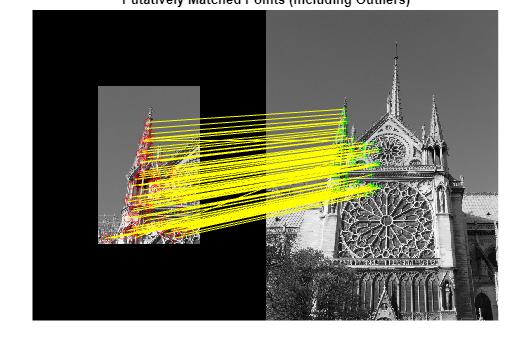

nImage = im2gray(imread("notredame2links.jpg"));
sImage = im2gray(imread("notredame.jpg"));
notrePoints = detectSURFFeatures(nImage);
scenePoints = detectSURFFeatures(sImage);
% Features aus beiden Bildern extrahieren
[boxFeatures, boxPoints] = extractFeatures(nImage, notrePoints);
[sceneFeatures, scenePoints] = extractFeatures(sImage, scenePoints);
% Matching features
notrePairs = matchFeatures(boxFeatures, sceneFeatures);

matchedNotrePoints = notrePoints(notrePairs(:, 1), :);
matchedScenePoints = scenePoints(notrePairs(:, 2), :);
figure;
showMatchedFeatures(nImage, sImage, matchedNotrePoints, ...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

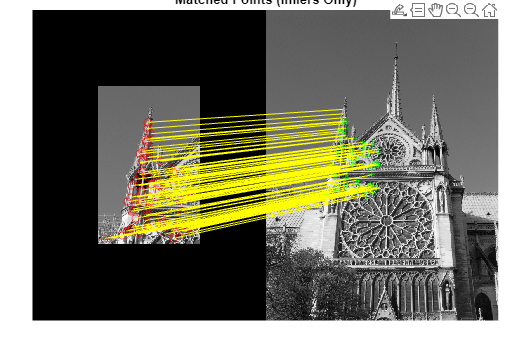


[tform, inlierIdx] = estgeotform2d(matchedNotrePoints, matchedScenePoints, 'affine');
inlierNotrePoints   = matchedNotrePoints(inlierIdx, :);
inlierScenePoints = matchedScenePoints(inlierIdx, :);

figure;
showMatchedFeatures(nImage, sImage, inlierNotrePoints, ...
    inlierScenePoints, 'montage');
title('Matched Points (Inliers Only)');

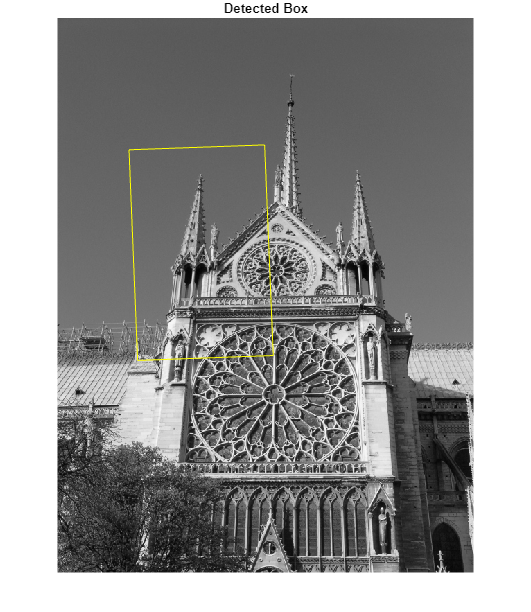


notrePolygon = [1, 1;...                           % top-left
        size(nImage, 2), 1;...                 % top-right
        size(nImage, 2), size(nImage, 1);... % bottom-right
        1, size(nImage, 1);...                 % bottom-left
        1, 1];                   % top-left again to close the polygon

newNotrePolygon = transformPointsForward(tform, notrePolygon);

figure;
imshow(sImage);
hold on;
line(newNotrePolygon(:, 1), newNotrePolygon(:, 2), Color='y');
title('Detected Box');

Die Linien in den Bildern sind nicht parallel weil das gesuchte Bild nicht 1 zu 1 im großen vorkommt es gibt eine perspektivische Verzerrung, das bedeutet das bild wurde entweder verzerrt oder aus einem anderen Winkel aufgenommen.